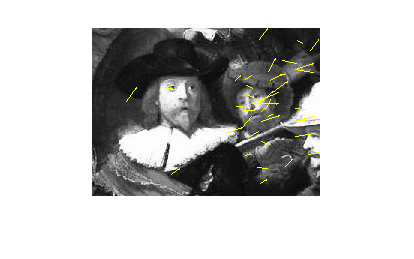

image1 = im2single(rgb2gray(imread('nachtwacht1.jpg')));
image2 = im2single(rgb2gray(imread('nachtwacht2.jpg')));
[F1, D1] = vl_sift(image1);
[F2, D2] = vl_sift(image2);
matches = vl_ubcmatch(D1, D2);
imshow(image1);

hold on ;
for match = matches(1, :)
    quiver(F1(1, match), F1(2, match), F1(3, match), F1(4, match), 3, 'y');
end
hold off;

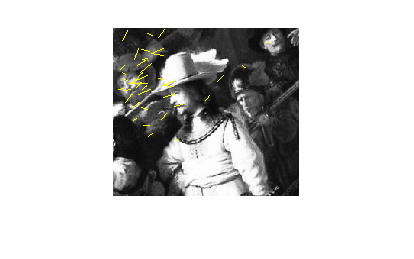

imshow(image2);

hold on ;
for match = matches(2, :)
    quiver(F2(1, match), F2(2, match), F2(3, match), F2(4, match), 3, 'y');
end
hold off;

for i = 1:4
    xy(:, i) = F1(1:2, matches(1, i));
    uv(:, i) = F2(1:2, matches(2, i));
end


projm = estimateProjectionMatrix(xy', uv')
diff = []


diff =

     []



for i = 5:size(matches, 2)
    Coords1 = projm * [F1(1:2, matches(1, i))', 1]';
    Coords1 = Coords1(1:2) / Coords1(3);
    Coords2 = F2(1:2, matches(2, i))';
    diff(i-4) = sqrt((Coords1(1)-Coords2(1))^2 + (Coords1(2)-Coords2(2))^2);
end
diff

diff =   203.4991   41.8121  124.2735   48.6038   34.4998  100.4002   62.0497    5.2679    8.4812   21.7931   42.7667   81.3599   24.6984  123.5694   12.7305   72.8346  236.2583  167.8929   56.6777   67.4227  198.8317   32.2516   26.0293   40.7196   95.5176  162.0425   31.7229   66.4258   66.4258  162.0728   53.6754   48.5857   48.5857   75.7153   32.5434   32.5434


The table above is the distance between the projected coordinates and the actual coordinates for every match.

The projection matrix isn't correct, and is not even close to being correct. Every transformed coordinate is pretty far off it's actual location. (Except for the first 4, which the transformation is based on, so they should be 0)

If the match was a bad match, the coordinates will not match if the projection matrix is correct and is used on the coordinates on one of the coordinates. point_1 * projection_matrix with a correct projection_matrix can only return return point_2 if they are actual matches, so if they are bad matches, the result of this projection will be miles off.

If the projection matrix is based on a bad match, the projection matrix itself will be wrong, and all projections made with this matrix will be incorrect. This is because the computer doesn't know that the match is wrong, and will use that match as a basis to create the projection matrix.

iterations = 16;
threshDist = 1;
inlierRatio = 8/size(matches, 2);
projm = ransacProjectionMatrix(F1, F2, matches, iterations, threshDist, inlierRatio)

projm =     0.0061    0.0016   -0.9548
   -0.0015    0.0059    0.2971
    0.0000   -0.0000    0.0064


for i = 1:size(matches, 2)
    Coords1 = projm * [F1(1:2, matches(1, i))', 1]';
    Coords1 = Coords1(1:2) / Coords1(3);
    Coords2 = F2(1:2, matches(2, i))';
    diff(i) = sqrt((Coords1(1)-Coords2(1))^2 + (Coords1(2)-Coords2(2))^2);
end
diff

diff =   136.9624    0.1160    0.1112    0.1832    0.4234    0.0114   86.3343    0.1113    0.1981    0.6348    0.9256  113.4140    0.4254    0.1386    0.7557    0.2925    0.1083  219.9728    0.0961    0.1019    0.1662    0.4104    0.0842    1.0145  272.0493    0.0672    0.3357    0.2420    0.2636  175.4079    0.1368    0.2182    0.2182  175.7780    0.2541    0.1278    0.1278    0.2457    0.1810    0.1810


T = maketform('projective', projm');
[x y] = tformfwd(T,[1 size(f1,2)], [1 size(f1,1)]);

Undefined function or variable 'f1'.



xdata = [min(1,x(1)) max(size(f2,2),x(2))];
ydata = [min(1,y(1)) max(size(f2,1),y(2))];
f12 = imtransform(f1,T,'Xdata',xdata,'YData',ydata);
f22 = imtransform(f2, maketform('affine', [1 0 0; 0 1 0; 0 0 1]), 'Xdata',xdata,'YData',ydata);
subplot(1,1,1);
imshow(max(f12,f22));

repeats = 1000;
failcount = 0;
for i = 1:repeats
    projm = ransacProjectionMatrix(F1, F2, matches, iterations, threshDist, inlierRatio);
    if (projm == 0)
        failcount = failcount + 1;
    end
end
(repeats-failcount)/repeats

log(1-0.98)/log(1-(1-0.175)^8)